# Clustering

clear;close all;clc
% change directory in order for relative references to work
cd(fileparts(matlab.desktop.editor.getActiveFilename))

This is our first contact with unsupervised learning. We will focus on k-means clustering and DBSCAN combined with a number of applications. Fuzzy clustering can also be done in Matlab using a Gaussian Mixture Model.

## K-means

K-means clustering is a form of clustering that is partitional and that used centroids. The number of clusters (K) is fixed before running the algorithm.

### Selection of inital poins

Suppose you have K ‘real’ clusters of the same size n. Plot the probability of obtaining an initial centroid from each cluster if the points are chosen at random. 

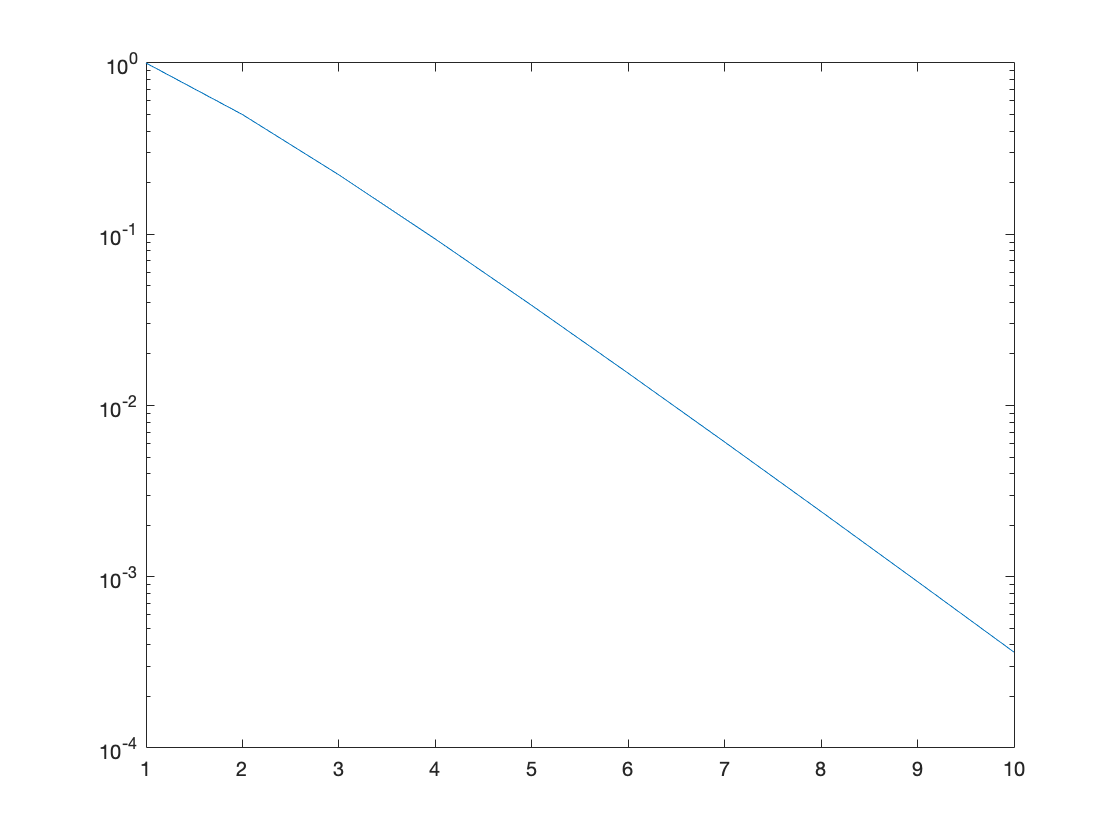

k = 1:10;
figure();
semilogy(k, factorial(k) ./ (k).^k)

Below you find an illustration of the basic use of the k-means implementation in Maltab. 

% make some rectangles (same size, different positions)
rng(1)
[coord, c] = kmeansdata([-1 -1 1 1], [-1 1 -1 1], [1 1 1 1], [1 1 1 1],100);

%% illustration using k-means++ (30 initialisations)
figure()
scatter(coord(:,1), coord(:,2),20,c,'o','filled'); hold on
% run multiple solutions (randomness in starting values
[~, C] = kmeans(coord, 4, "Display","final","Replicates",30);

Replicate 1, 6 iterations, total sum of distances = 157.166.
Replicate 2, 3 iterations, total sum of distances = 157.166.
Replicate 3, 6 iterations, total sum of distances = 157.166.
Replicate 4, 4 iterations, total sum of distances = 157.166.
Replicate 5, 3 iterations, total sum of distances = 157.166.
Replicate 6, 4 iterations, total sum of distances = 157.166.
Replicate 7, 6 iterations, total sum of distances = 157.166.
Replicate 8, 5 iterations, total sum of distances = 157.166.
Replicate 9, 3 iterations, total sum of distances = 157.166.
Replicate 10, 3 iterations, total sum of distances = 157.166.
Replicate 11, 4 iterations, total sum of distances = 157.166.
Replicate 12, 3 iterations, total sum of distances = 157.166.
Replicate 13, 4 iterations, total sum of distances = 157.166.
Replicate 14, 7 iterations, total sum of distances = 157.166.
Replicate 15, 3 iterations, total sum of distances = 157.166.
Replicate 16, 5 iterations, total sum of distances = 157.166.
Replicate 17, 4 i

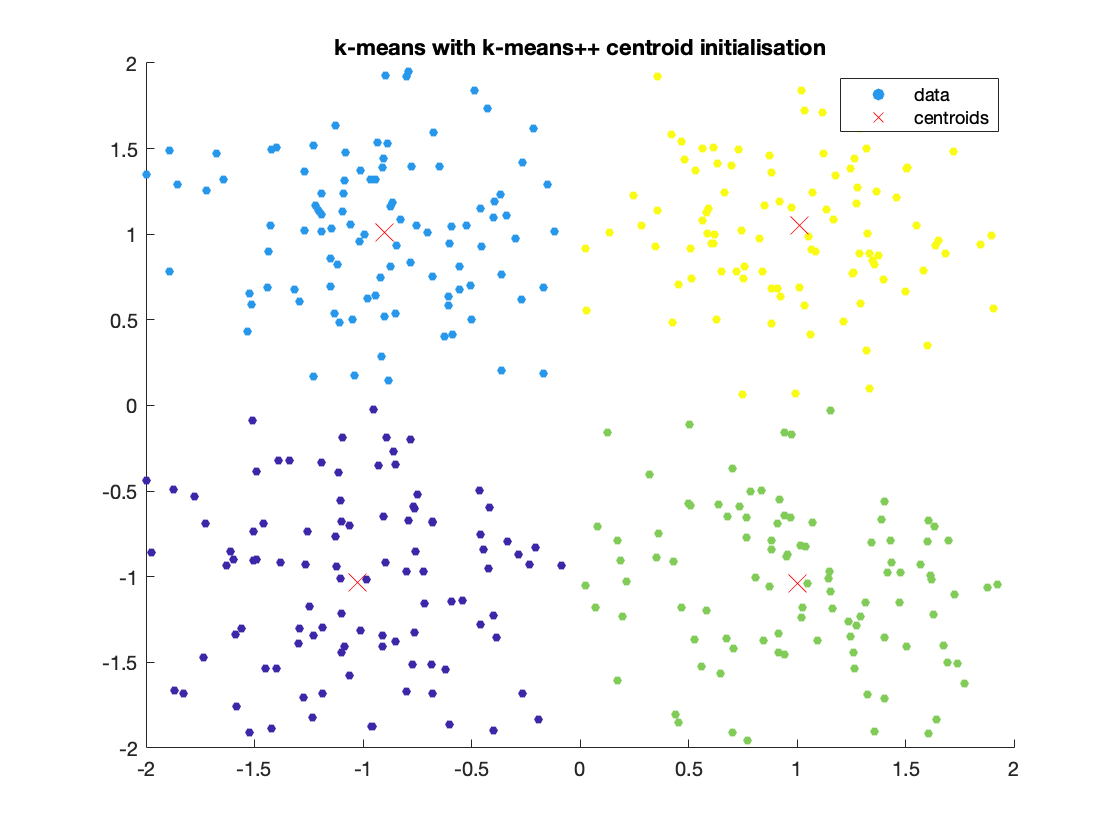

scatter(C(:,1), C(:,2),100,'x','red');
legend(["data", "centroids"]);
title('k-means with k-means++ centroid initialisation')

If you look into how the initial points are chosen, by default the k-means++ algorithm is chosen, in order to avoid the sensitivity of k-means clustering with respect to the initial point. The effect of choosing randrom centroids is shown below

%% illustration using random points (30 initialisations)
figure()
scatter(coord(:,1), coord(:,2),20,c,'o','filled'); hold on
% run multiple solutions (randomness in starting values)
[~, C] = kmeans(coord, 4, "Display","final",'Start',"sample",'Replicates',30);

Replicate 1, 15 iterations, total sum of distances = 157.166.
Replicate 2, 5 iterations, total sum of distances = 157.166.
Replicate 3, 4 iterations, total sum of distances = 157.166.
Replicate 4, 4 iterations, total sum of distances = 157.166.
Replicate 5, 10 iterations, total sum of distances = 157.166.
Replicate 6, 8 iterations, total sum of distances = 157.166.
Replicate 7, 9 iterations, total sum of distances = 157.166.
Replicate 8, 3 iterations, total sum of distances = 157.166.
Replicate 9, 11 iterations, total sum of distances = 157.166.
Replicate 10, 6 iterations, total sum of distances = 157.166.
Replicate 11, 6 iterations, total sum of distances = 157.166.
Replicate 12, 5 iterations, total sum of distances = 157.166.
Replicate 13, 17 iterations, total sum of distances = 157.166.
Replicate 14, 4 iterations, total sum of distances = 157.166.
Replicate 15, 3 iterations, total sum of distances = 157.166.
Replicate 16, 6 iterations, total sum of distances = 157.166.
Replicate 17,

scatter(C(:,1), C(:,2),100,'x','red');
legend(["data", "centroids"]);
title('k-means with k-means++ centroid initialisation')

### Effect of outliers

We generate the same data as before, but this time we add an outlier point

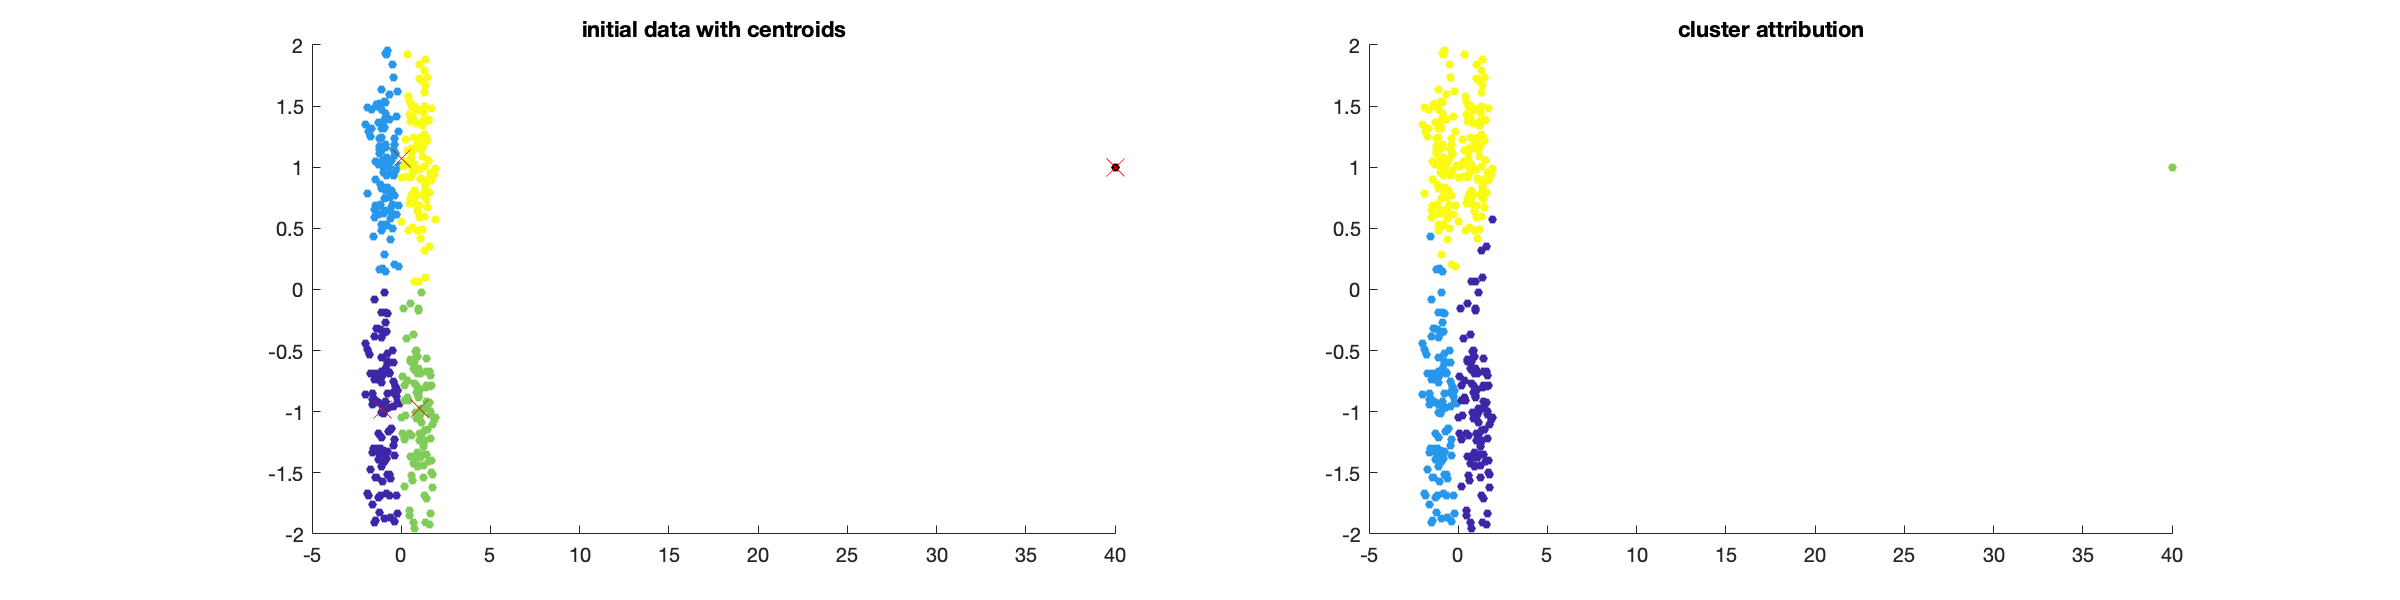

% make some rectangles (same size, different positions)
rng(1)
[coord, c] = kmeansdata([-1 -1 1 1], [-1 1 -1 1], [1 1 1 1], [1 1 1 1],100);
coord = [coord;[40 1]];
c = [c; repmat([0 0 0],1,1)];

%% illustration using k-means++ (30 initialisations)
[idx, C] = kmeans(coord, 4, "Display","off",'Start',"sample",'Replicates',30);

figure("Position",[0 0 1200 300])
subplot(1,2,1)
scatter(coord(:,1), coord(:,2),20,c,'o','filled'); hold on
scatter(C(:,1), C(:,2),100,'x','red');
title("initial data with centroids")
subplot(1,2,2)
cc = getcolors(idx-1);
scatter(coord(:,1), coord(:,2),20,cc,'o','filled')
title("cluster attribution")

Can you explain what is happening here?

### Deciding on the optimal number of clusters

For some applications we are able to set an appropriate number of clusters beforehand (e.g. for number recognition).  For other problems, we might not always have an idea. Below we show a number of metrics you can use:

#### Elbow method

the method consists of plotting the cluster inertia in function of the number of clusters k. A good guess for k is the elbow point in the graph. 

*note*: the cluster inertia is the intra-cluster variance and is defined as


$$I=\sum_c \sum_{i=1\ldotp \ldotp \ldotp n_c } {d\left(i,{\textrm{centroid}}_c \right)}^2$$


% generate sample
[coord, ~] = kmeansdata([-1 -1 1 1], [-1 1 -1 1], [1 1 1 1], [1 1 1 1],100);
% compute cluster inertia(s)
K = 1:10;
CI = zeros(size(K));
S = zeros(size(K));
D = zeros(size(K));
for k = K
    % run clustering
    [idx, C] = kmeans(coord, k,"Distance","sqeuclidean");
    % get value
    CI(k) = clusterinertia(coord, idx, C);
    if k > 1
        S(k) = silhouettecoef(coord, idx, C);
        D(k) = daviesbouldin(coord, idx, C);
    end
end
% infer elbow point
cidx = findchangepts(CI, "Statistic","linear");

% illustration
figure
t = tiledlayout(1,3);
t.Title.String = "finding the optimal k";
t.Title.FontSize = 20;
nexttile
plot(K, CI); hold on;
plot(K(cidx), CI(cidx),'xr')
%xticks()
xlabel("k")
ylabel("clustering inertia")
title("elbow method")

#### Silhouette analysis

You will use the silhouette coefficient S, which is computed as the average coefficient over all data points:


$$S=\frac{1}{n}\sum_i S_i$$


with $S_i =\frac{b_i -a_i }{\mathrm{max}\left(a_i ,b_i \right)}$, where $a_i$ denotes the average distance between point i and all other points in the same cluster and $b_i$ denotes the average distance between the point i and all data points from the nearest cluster. The higher S, the better the clustering.

nexttile
plot(K(2:end), S(2:end))
[~,maxind] = max(S);
hold on
plot(K(maxind), S(maxind),'xr')
xlabel("k")
ylabel("S")
title("silhouette coefficient")



#### Davies-Bouldin index

Consider the following metrics 

- $d_i$: the average distance between each point in cluster i and its centroid

- $d_{\mathrm{ij}}$: the distance between the centroids of cluster i and cluster j

- $D_{\mathrm{ij}} =\frac{d_i +d_j }{d_{\mathrm{ij}} }$: the Davies-Boulding index for a specific pair of clusters

For each cluster i we will compute all pairwise values $D_{\mathrm{ij}\;} \left(i\not= j\right)$. The maximum value is retained. The total value for the given clustering is given by the mean of these maximal values. The smaller the total value, the better

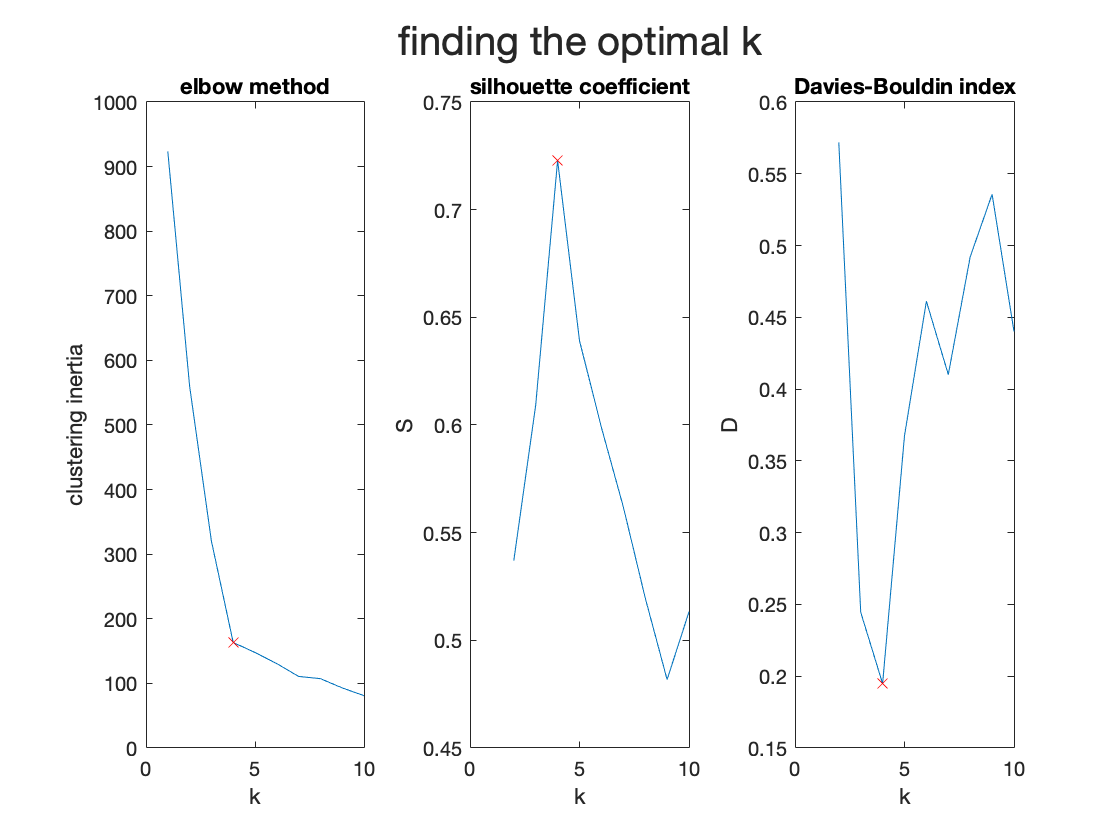

nexttile
plot(K(2:end), D(2:end))
[~,maxind] = min(D(2:end));
hold on
plot(K(maxind+1), D(maxind+1),'xr')
xlabel("k")
ylabel("D")
title("Davies-Bouldin index")

### Distance metrics

Different distance metrics are available (cf. documentation) and can be used. An exhaustive overview can be found [here](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0144059).

### Curse of dimensionality

As the number of dimensions increases, a distance-based similarity measure converges to a constant value between any given examples. Below we illustrate this for the euclidean distance with increasing dimensions. We generate 500 random points and increase the dimensionality of the data. As you can see, when the number of dimension increases, the coefficient of variation (sigma/mu, a standardized measure of dispersion) is increasingly smaller. In practice this means that the higher the number of dimensions, the more our datapoints appear equidistant of one another. 

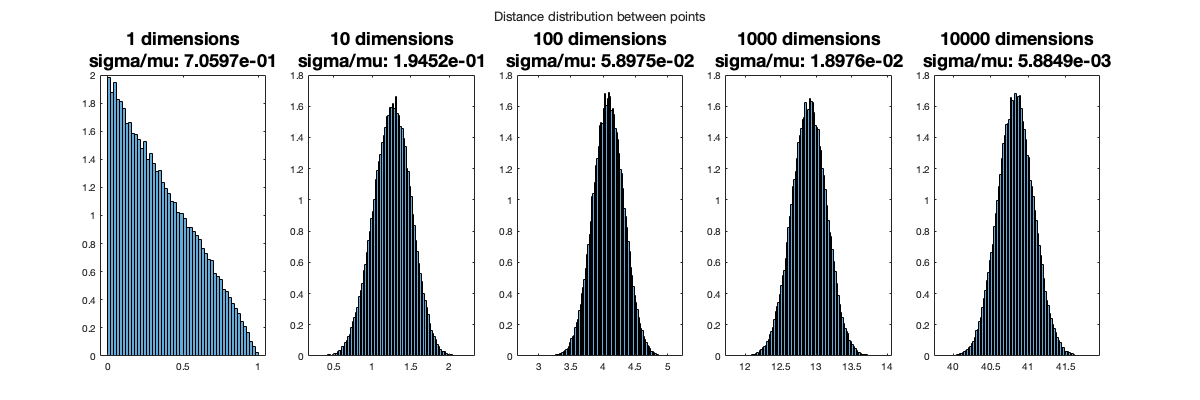

dims = [1 10 100 1000 10000];
figure("Position",[0 0 1200 400])
t = tiledlayout(1,length(dims));
t.Title.String = 'Distance distribution between points';

for d = dims
    nexttile
    % generate data
    X = rand(500, d);
    % compute distance matrix
    dd = pdist(X,"euclidean");
    % histogram
    h = histogram(dd,'Normalization',"pdf");
    title([sprintf("%i dimensions",d); sprintf("sigma/mu: %1.4e",std(dd)/mean(dd))],'FontSize',18)
end

## Application 1 - clustering applied to handwritten number recognition

We illustrate the principle of clustering and apply it to the handwritten numbers dataset

clear
% Load up the data
D = readtable('./Data/MNIST-train.csv');
% use only 10% of data for training
part = cvpartition(D.label,"HoldOut", 0.9, "Stratify", true);
% limit data for computation
d = D(part.training,:);
X = d{:,2:end};
Y = d{:,1};

We run the clustering on the data:

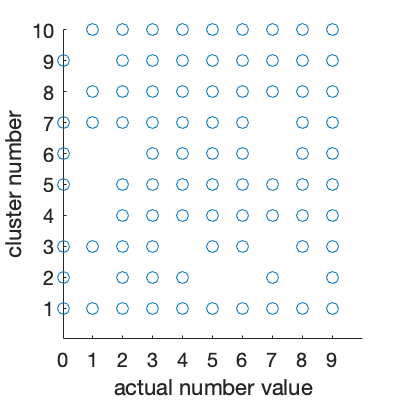

idx = kmeans(X, 10);
figure("Position",[0 0 200 200])
scatter(Y,idx)
xlabel('actual number value');
ylabel('cluster number')
xticks(0:9); yticks(1:10);

As you can see, this does not look promising. You can obtain a better view of the situation by looking at the repartion of the numbers within each cluster:

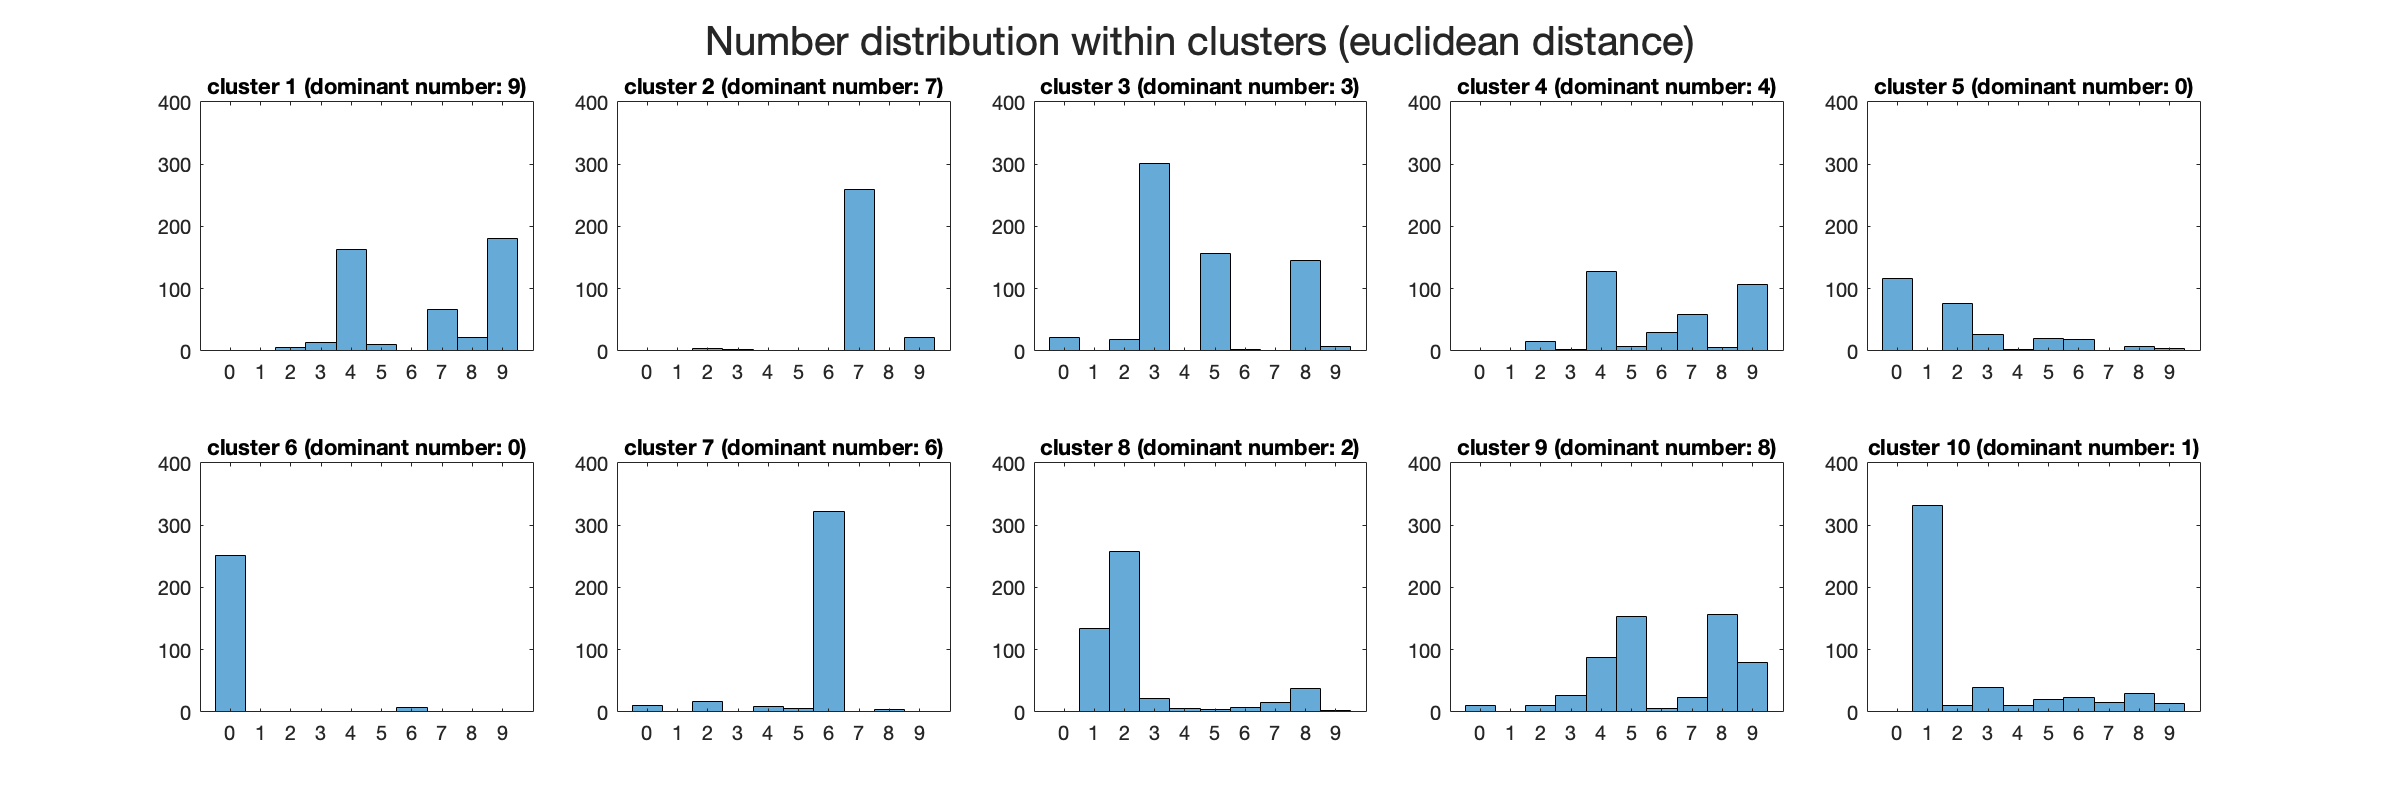

figure("Position",[0 0 1200 400])
t = tiledlayout(2,5);
t.Title.String = 'Number distribution within clusters (euclidean distance)';
t.Title.FontSize = 20;
xvals = 0:9;

for k = 1:10
    % members of cluster k
    finds = idx == k;
    nexttile
    h = histogram(Y(finds),"BinEdges",-0.5:1:9.5);
    [~,I] = max(h.Values);
    title(sprintf('cluster %i (dominant number: %i)',k, xvals(I) ));
    xticks(xvals)
    ylim([0 400])
end

Maybe it is due to the distance metric we used? Let's try something else

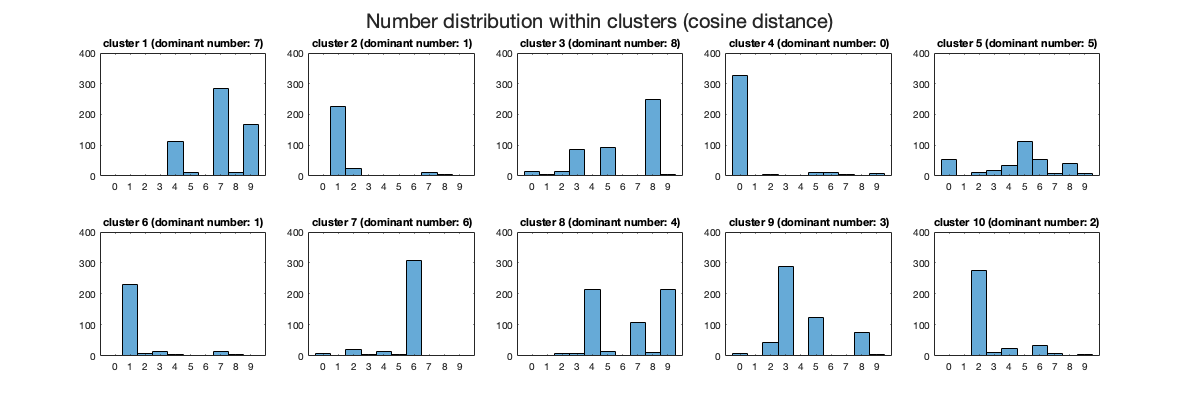

idx = kmeans(X, 10,"Distance","cosine");
figure("Position",[0 0 1200 400])
t = tiledlayout(2,5);
t.Title.String = 'Number distribution within clusters (cosine distance)';
t.Title.FontSize = 20;
for k = 1:10
    % members of cluster k
    finds = idx == k;
    nexttile
    h = histogram(Y(finds),"BinEdges",-0.5:1:9.5);
    [~,I] = max(h.Values);
    title(sprintf('cluster %i (dominant number: %i)',k, xvals(I) ));
    xticks(0:9)
    ylim([0 400])
end

Can you explain what is happening here? Is the cosine distance different with respect to the euclidean distance?

#### Overcoming our problems

In one of the lecture videos, you have seen t-SNE (t-distributed Stochastic Neighbor Embedding). t-SNE is a nonlinear dimensionality reduction technique (another technique for dimension reduction is Principal Component Analysis - PCA - but this one cannot retain non-linear variance) that is well suited for embedding high dimension data into lower dimensional data (2D or 3D) for data visualization.This is also available in Matlab. We can try this and see if some useful information is revealed.

% tsne reduction to two dimensions (non-linear)
Xtsne2 = tsne(X,"NumDimensions",2);
% tsne reduction in three dimensions (non-linear)
Xtsne3 = tsne(X,"NumDimensions",3);
% PCA reduction in two dimension (linear)
[~,Xpca,~] = pca(X);

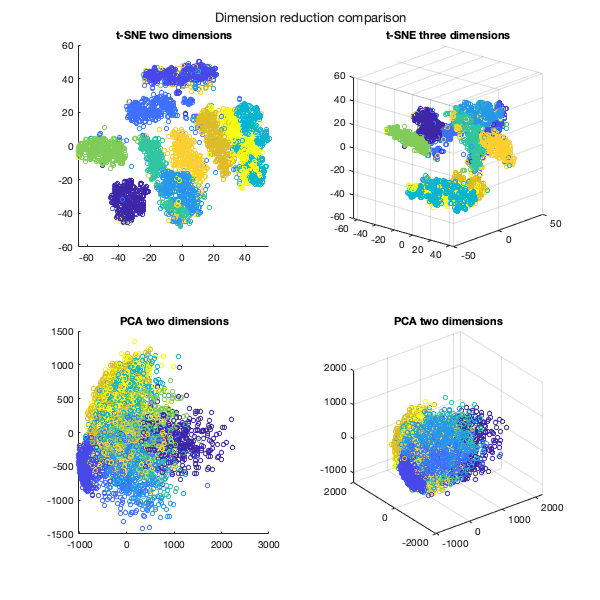

Yc = getcolors(Y);
% illustration
figure("Position",[0 0 600 600])
t = tiledlayout(2,2);
t.Title.String = "Dimension reduction comparison";
nexttile
scatter(Xtsne2(:,1), Xtsne2(:,2), 20 ,Yc)
title("t-SNE two dimensions")
nexttile
scatter3(Xtsne3(:,1), Xtsne3(:,2), Xtsne3(:,3),20, Yc)
title("t-SNE three dimensions")
nexttile
scatter(Xpca(:,1),Xpca(:,2), 20 ,Yc)
title("PCA two dimensions")
nexttile
scatter3(Xpca(:,1),Xpca(:,2),Xpca(:,3), 20 ,Yc)
title("PCA two dimensions")

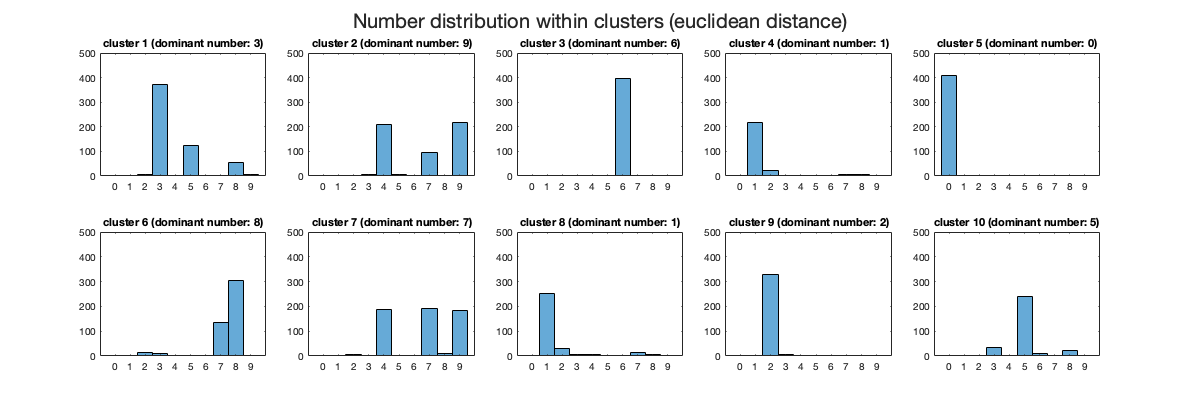

% Run the clustering in the reduced space
idx = kmeans(Xtsne2, 10);
figure("Position",[0 0 1200 400])
t = tiledlayout(2,5);
t.Title.String = 'Number distribution within clusters (euclidean distance)';
t.Title.FontSize = 20;
for k = 1:10
    % members of cluster k
    finds = idx == k;
    nexttile
    h = histogram(Y(finds),"BinEdges",-0.5:1:9.5);
    [~,I] = max(h.Values);
    title(sprintf('cluster %i (dominant number: %i)',k, xvals(I) ));
    xticks(0:9)
    ylim([0 500])
end

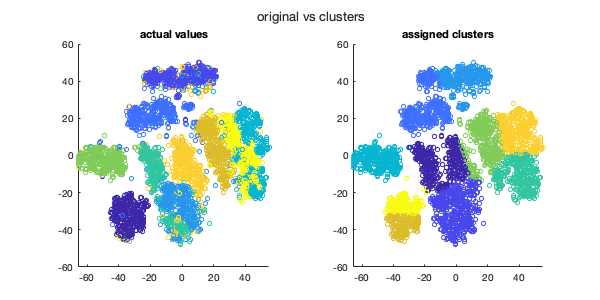

% illustrating the clusters
idx = kmeans(Xtsne2, 10);
Ycc = getcolors(idx-1);
% illustration
figure("Position",[0 0 600 300])
t = tiledlayout(1,2);
t.Title.String = "original vs clusters";
nexttile
scatter(Xtsne2(:,1), Xtsne2(:,2), 20 ,Yc)
title("actual values")
nexttile
scatter(Xtsne2(:,1), Xtsne2(:,2), 20 ,Ycc)
title("assigned clusters")

What other limitation of k-means clustering do you discover here?

## Application 2 - Clustering applied to text

clear; close all; clc

A text document can be represented as a vector in a high dimensional space. We will use a [TF-IDF encoding](https://en.wikipedia.org/wiki/Tf–idf) scheme to encode the texts: 


$$\mathrm{tfidf}\left(t,d,D\right)=\mathrm{tf}\left(t,d\right)\mathrm{idf}\left(t,D\right)=\frac{f_{t,d} }{\sum_{t^{\prime } \in d} f_{t^{\prime } ,d} }\cdot \mathrm{log}\left(\frac{N}{\left|\left\lbrace d\in D:t\in d\right\rbrace \right|}\right)$$


We will be using some news articles that were collected from the BBC website in two different categories, one set of articles is food related and the other one is science related. In general, these two domains do not have a lot of overlap, so we should be able to separate them nicely. In order to realize this we need to go over a number of steps:

- obtain the raw data

- preprocess the raw data

- obtain our bag of words representation. This is stored as a vocabulary list and a sparse matrix representation of the documents.

- obtain the TF-IDF values.

- do the actual clustering on the vectorized data.

% initialize bag of words object
bag = bagOfWords();
% load up the data into our bag of words
foodfolder = "Data/textclustering/food/";
sciencefolder = "Data/textclustering/science/";
[bag, f, c] = preprocesstext(bag, foodfolder);
[bag, ~, c] = preprocesstext(bag, sciencefolder,f,c);
% transform our bag of word representation into a TF-IDF matrix:
X = tfidf(bag);

% do the clustering
idx = kmeans(X,2,"Replicates",30,"Display","final");

Replicate 1, 1 iterations, total sum of distances = 134042.
Replicate 2, 1 iterations, total sum of distances = 135578.
Replicate 3, 1 iterations, total sum of distances = 132989.
Replicate 4, 1 iterations, total sum of distances = 132989.
Replicate 5, 1 iterations, total sum of distances = 134042.
Replicate 6, 1 iterations, total sum of distances = 136015.
Replicate 7, 1 iterations, total sum of distances = 127822.
Replicate 8, 1 iterations, total sum of distances = 132989.
Replicate 9, 1 iterations, total sum of distances = 134142.
Replicate 10, 1 iterations, total sum of distances = 135578.
Replicate 11, 1 iterations, total sum of distances = 132989.
Replicate 12, 1 iterations, total sum of distances = 134916.
Replicate 13, 1 iterations, total sum of distances = 136015.
Replicate 14, 1 iterations, total sum of distances = 136665.
Replicate 15, 1 iterations, total sum of distances = 129400.
Replicate 16, 1 iterations, total sum of distances = 136015.
Replicate 17, 1 iterations, total

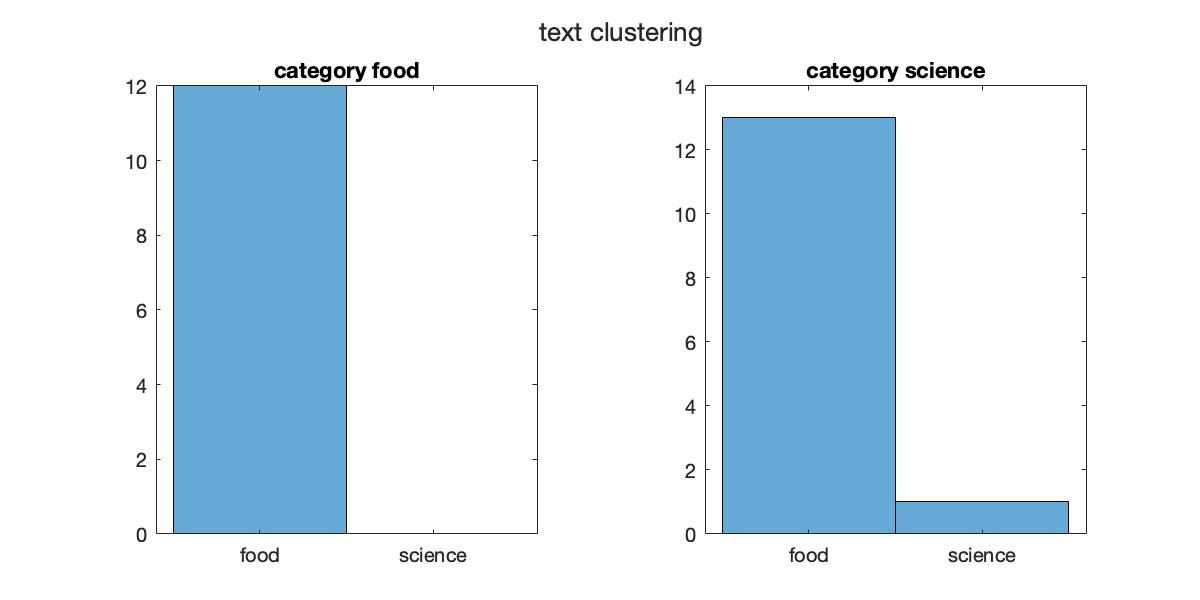

% make an illustration
figure()
figure("Position",[0 0 600 300])
t = tiledlayout(1,2);
t.Title.String = "text clustering";
labels = unique(c);
for i = 1:length(labels)
    nexttile
    filt = c == labels(i);
    dist = idx(filt);
    histogram(dist,"BinEdges",[1/2 3/2 5/2])
    title(sprintf("category %s", labels(i)))
    xticks([1 2])
    xticklabels(["food" "science"])
end

Once again, this already is a nice result. A different distance metric might provide a better solution.

% do the clustering
idx = kmeans(X,2,"Distance","cosine","Replicates",30,"Display","final");

Replicate 1, 1 iterations, total sum of distances = 17.7336.
Replicate 2, 1 iterations, total sum of distances = 17.784.
Replicate 3, 1 iterations, total sum of distances = 18.3229.
Replicate 4, 1 iterations, total sum of distances = 17.9346.
Replicate 5, 1 iterations, total sum of distances = 17.7973.
Replicate 6, 1 iterations, total sum of distances = 17.8951.
Replicate 7, 1 iterations, total sum of distances = 18.0932.
Replicate 8, 1 iterations, total sum of distances = 17.8687.
Replicate 9, 1 iterations, total sum of distances = 17.8151.
Replicate 10, 1 iterations, total sum of distances = 17.9776.
Replicate 11, 1 iterations, total sum of distances = 17.7597.
Replicate 12, 1 iterations, total sum of distances = 17.949.
Replicate 13, 1 iterations, total sum of distances = 17.822.
Replicate 14, 1 iterations, total sum of distances = 17.7597.
Replicate 15, 1 iterations, total sum of distances = 17.8719.
Replicate 16, 1 iterations, total sum of distances = 18.4939.
Replicate 17, 1 iter

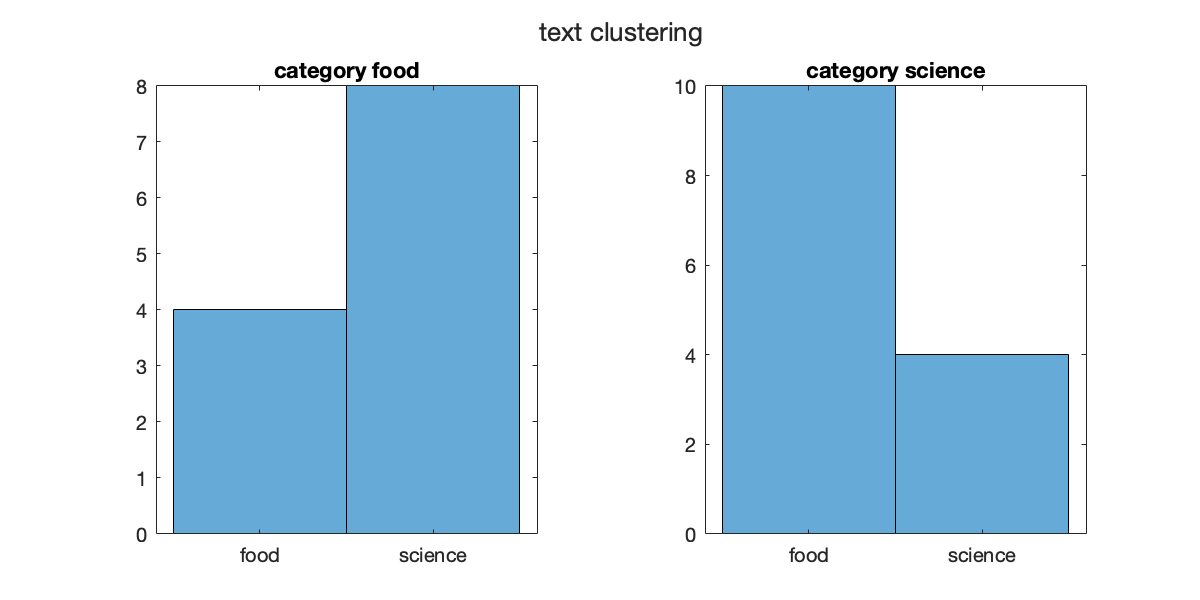

% make an illustration
figure()
figure("Position",[0 0 600 300])
t = tiledlayout(1,2);
t.Title.String = "text clustering";
labels = unique(c);
for i = 1:length(labels)
    nexttile
    filt = c == labels(i);
    dist = idx(filt);
    histogram(dist,"BinEdges",[1/2 3/2 5/2])
    title(sprintf("category %s", labels(i)))
    xticks([1 2])
    xticklabels(["food" "science"])
end

Although we are dealing with high-dimensional data again, this time the cosine similarity and euclidean distance do seem to work, can you explain why?

#### Making things better again

We will also use a slightly different approach for the clustering process. Instead of using k-means, we will be using k-medoids. The main difference with the k-means algorithm algorithm is that the k-medoids uses actual data points as centers (called medoids) and it can be used with arbitrary distance measures. In k-means, the mean is greatly influenced by outliers and thus cannot represent the correct cluster center, while in k-medoids, the medoid is robust to the outlier and is able to represent the cluster center correctly.

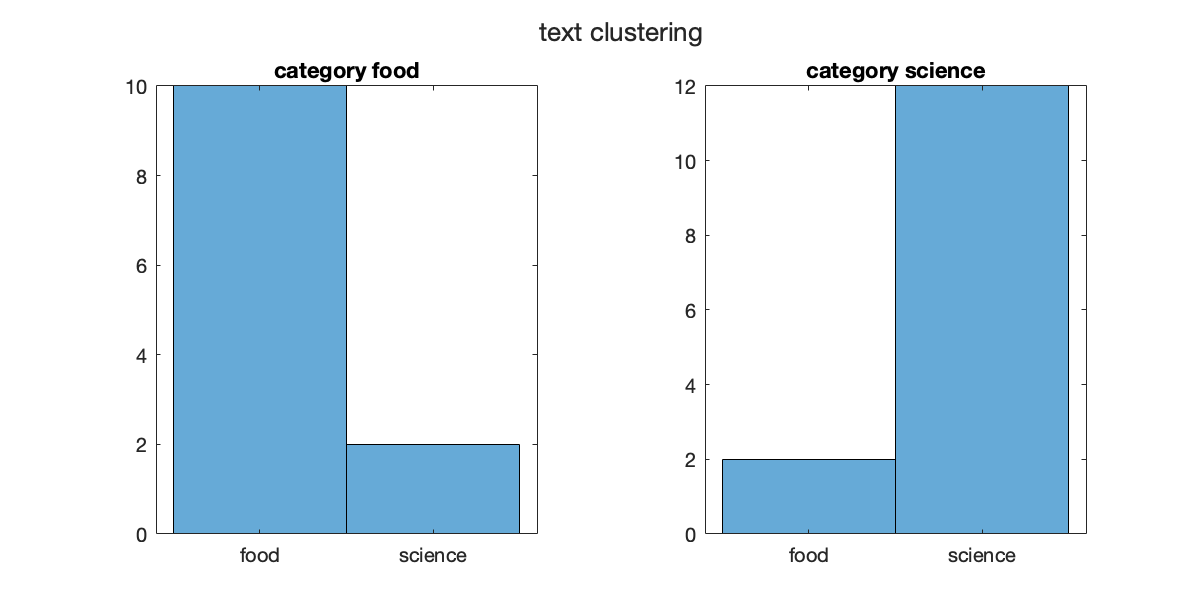

% do the clustering
idx = kmedoids(X,2,"Distance","cosine","Replicates",30);
% make an illustration
figure()
figure("Position",[0 0 600 300])
t = tiledlayout(1,2);
t.Title.String = "text clustering";
labels = unique(c);
for i = 1:length(labels)
    nexttile
    filt = c == labels(i);
    dist = idx(filt);
    histogram(dist)
    title(sprintf("category %s", labels(i)))
    xticks([1 2])
    xticklabels(["food" "science"])
end

## Hierarchical clustering

This is a different approach, where each data points is in its own cluster at the start. Clusters are combined progressively until the final cluster is reached (all data points grouped together). The combination of the clusters can be done in differents ways:

- single linkage: use the minimum distance between any of the cluster members

- average linkage: use the mean distance between any of the cluster members

- complete linkage: use the maximum distance between any of the members

- etc.

As we have seen before, the notion "distance" is required once more. We will start with a simple example to illustrate the principle.

In practive you have three steps in the clustering process:

- determine the distance matrix

- build the cluster tree

- determine the cut-off point

The entire process can be done using the **clusterdata** instruction or you can run each subprocess individually.

clear; clc;
% use uniform distrubition for datapoints
d = makedist("Uniform","lower",1,"upper",3);
% set random seed for reproducibility
rng(173);
% get data
X = random(d,5,2);
% cluster the data (all steps separately)
% - distance "matrix" (stored as vector using upper diagonal)
D = pdist(X, "euclidean");
% - tree structure (stored as nodes merging and the distance value)
Zs = linkage(D, "single");
Zc = linkage(D, "complete");
% - cut-off (using the distances)
cval = 0.5;
Ts = cluster(Zs,'Cutoff',cval,"criterion","distance");
Tc = cluster(Zc,'Cutoff',cval,"criterion","distance");

Note: by default Matlab uses inconsistency to determine the how to split the clusters (cf. below). You can also specify that you want to use distance as a cut-off by specifying the *criterion* in the options of cluster.The clusters found using inconsistency may, but do not necessarily, correspond to a horizontal slice across the dendrogram at a certain height.

The vector D is of size 1x10. It contains the unique pairwise comparisons in a columnwise manner. You can facilitate interpreting D by using **squareform**. The matrix Zs contains the clusters that are combined at each step (first two columns) as well the distance between them. Try to retrace the values found in Zs.

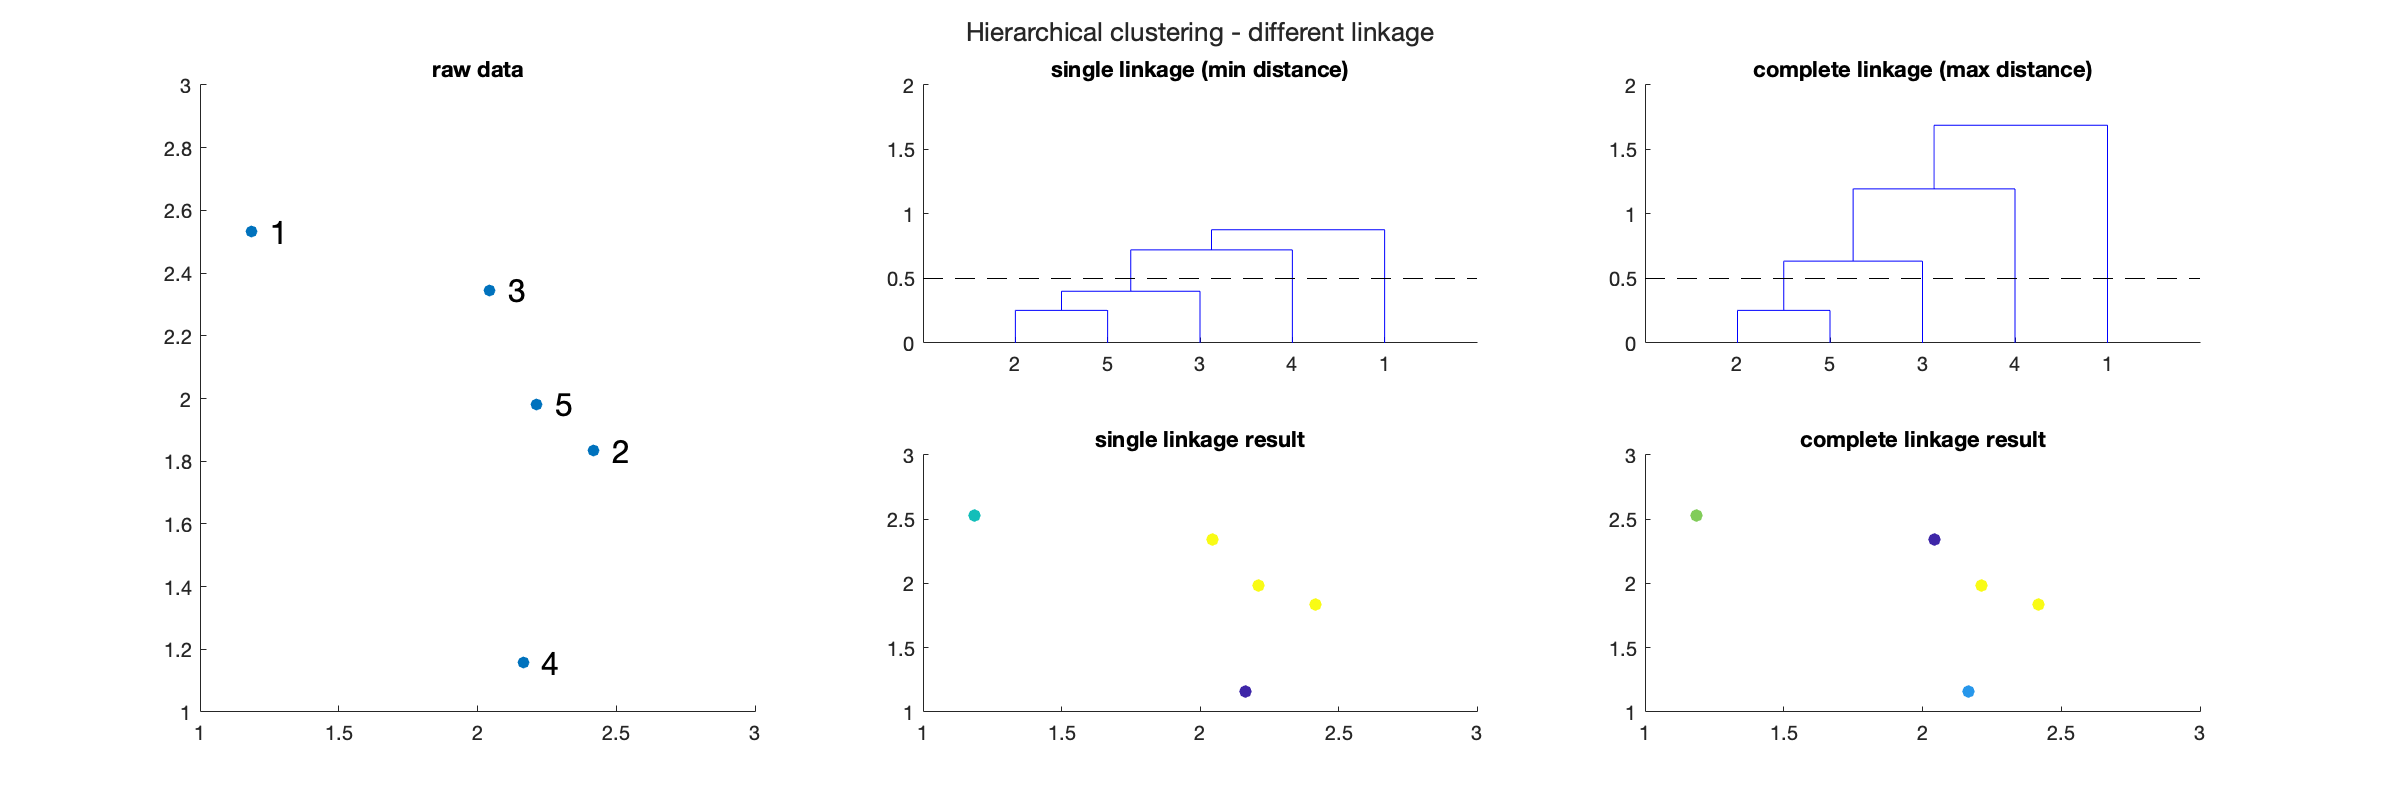

squareform(D)

% illustration
figure("Position",[0 0 1200 400])
t = tiledlayout(2,3);
t.Title.String = "Hierarchical clustering - different linkage";
nexttile(1,[2 1])
scatter(X(:,1),X(:,2),"filled")
for i = 1:length(X)
    text(X(i,1),X(i,2), sprintf("  %i",i),'FontSize',16);
end
xlim([1 3]);ylim([1 3])
title("raw data")
nexttile(2)
dendrogram(Zs);hold on
ylim([0 2])
plot(0:length(X)+1, cval*ones(length(X)+2,1),'--k')
title("single linkage (min distance)")
nexttile
dendrogram(Zc);hold on
ylim([0 2])
plot(0:length(X)+1, cval*ones(length(X)+2,1),'--k')
title("complete linkage (max distance)")
nexttile
scatter(X(:,1),X(:,2),40,getcolors(Ts-1),"filled")
xlim([1 3]);ylim([1 3])
title("single linkage result")
nexttile

scatter(X(:,1),X(:,2),40,getcolors(Tc-1),"filled")
title("complete linkage result")
xlim([1 3]);ylim([1 3])

### Controlling and evaluating the cluster combinations

#### Consistency

The matrix Tx contains the cluster assignments. This assigment is based on a cut-off value either for the distance (cf. previous example) or for the consistency of the links. A link is said to be consistent if it is approximately the same height as the links below it. This comes down to the distance between the objects being joined being approximately the same as the distances between the objects already contained in the links. Inconsistent links can indicate the border of a natural division in a data set. 

Let's redo the single linkage clustering using the consistency as a criterion:

TTs = cluster(Zs,'Cutoff',cval,"criterion","inconsistent");

You can compute the values of the consistency coefficient with **inconsistent**. The first column containts the mean of all involved heights, the second one the variance of all involved heights, the third one the number of links included in the computation and the fourth column containts the consistency coefficient. The consistency coefficient can be written as:


$$c=\frac{Z_{\mathrm{link}} -\bar{Z} }{\sigma_Z }$$


with $Z_{\mathrm{link}}$ representing the distance associated with the linkage, $\bar{Z}$ the average distances and $\sigma_Z$ the standard deviation.

% consistency coefficient
I = inconsistent(Zs)
% reproduction of second row:

I =     0.2533         0    1.0000         0
    0.3273    0.1047    2.0000    0.7071
    0.5618    0.2269    2.0000    0.7071
    0.8001    0.1102    2.0000    0.7071


[mean(Zs(1:2,3)) std(Zs(1:2,3)) 2 (Zs(2,3)-mean(Zs(1:2,3)))/std(Zs(1:2,3))]
% reproduction of third row:

ans =     0.3273    0.1047    2.0000    0.7071


[mean(Zs(2:3,3)) std(Zs(2:3,3)) 2 (Zs(3,3)-mean(Zs(2:3,3)))/std(Zs(2:3,3))]
% reproduction of fourth row:

ans =     0.5618    0.2269    2.0000    0.7071


[mean(Zs(3:4,3)) std(Zs(3:4,3)) 2 (Zs(4,3)-mean(Zs(3:4,3)))/std(Zs(3:4,3))]
% Graphical illustration

ans =     0.8001    0.1102    2.0000    0.7071


%figure
figure("Position",[0 0 1200 400])
t = tiledlayout(1,2);
t.Title.String = "Hierarchical clustering - single linkage, consistency";
t.Title.FontSize = 22;
nexttile(1)
dendrogram(Zs); hold on
ylim([0 1.2])

% first combination (single link, no variance)
annotation("doublearrow",[0.135 0.135],[1.05/10, 2.55/10])
text(0.5,0.15,sprintf('%1.2f',Zs(1,3)))

% second combination (two links)
annotation("doublearrow",[0.26 0.26],[1.05/10, 3.4/10])
text(2.5,0.2,sprintf('%1.2f',Zs(2,3)))


text(0.25,1.2,"linkage of \{2,5\} and \{3\}:", 'FontSize',14)
text(0.25,1.1,sprintf('mean height: %1.4f',I(2,1)), 'FontSize',14)
text(0.25,1,sprintf('std height: %1.4f',I(2,2)), 'FontSize',14)
text(0.25,0.85,sprintf('consistency\ncoefficient: %1.4f',I(2,4)), 'FontSize',14)
title("Consistency coefficient illustration","FontSize",16)
ylim([0 1.3])


nexttile(2)
scatter(X(:,1),X(:,2),40,getcolors(TTs-1),"filled")
title("Resulting clusters", 'FontSize',16)

#### Quality of clustering - Dissimilarity

The height of the link represents the distance between the two clusters. This height is also known as the cophenetic distance between the two objects. another way to measure how well the cluster tree generated by the linkage function reflects the data is to compare the cophenetic distances with the original distance data. If the clustering is valid, the linking of objects in the cluster tree should have a strong correlation with the distances between objects in the distance vector. You can realize this with the **cophenet** function. The closer the value of the cophenetic correlation coefficient is to 1, the more accurately the clustering solution reflects your data. 

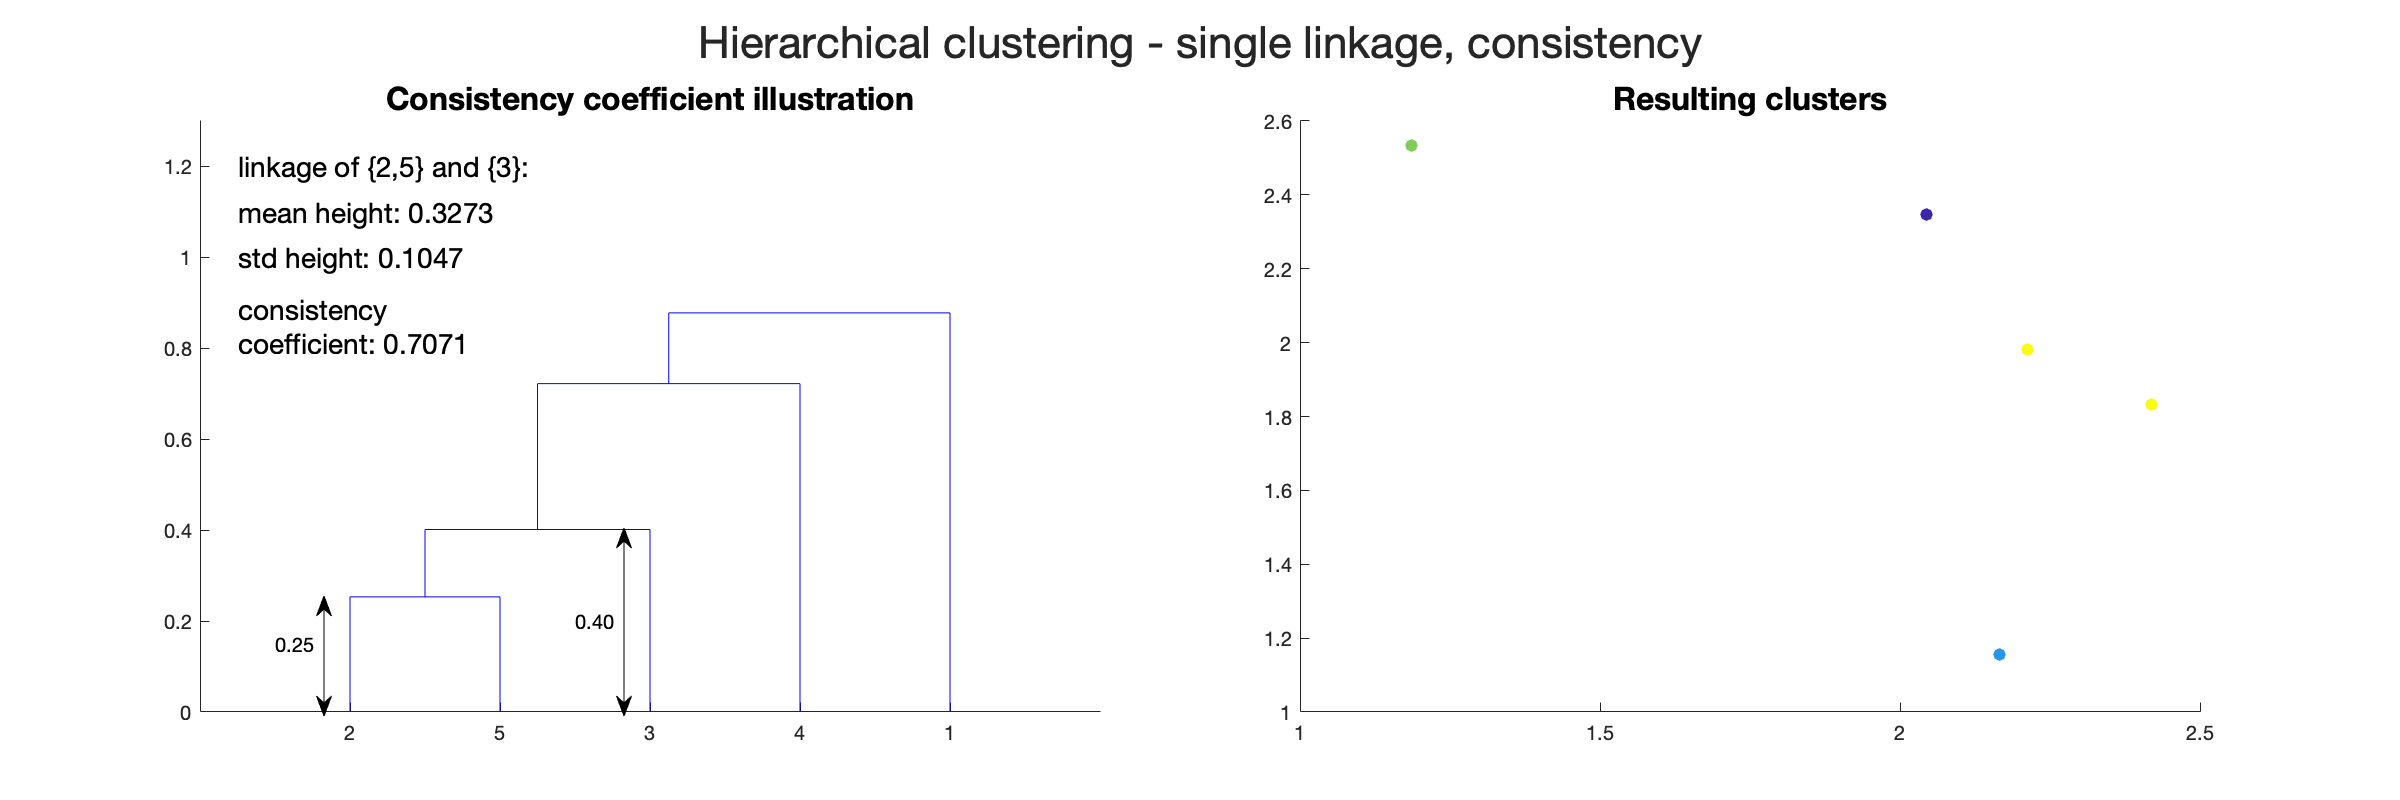

cophenet(Zs,D)

### Application 3 - hierarchical clustering for similar topics

Clustering has a wide range of applications. We will consider the following situation:

- We collect social media data

- we want to use hashtags to identify trends

We wish to use the (relative) volume or the increase in volume of a specific hashtag as an indicator of an emerging trend. From experience we know that different hashtags can co-occur whilst talking about the same phenomenon (different spelling, small variant, semantic link etc.) 

We will use hierarchical clustering combined with a text similarity measure to tackle this problem. We can use (among a lot of other options) the [dice similarity](https://en.wikipedia.org/wiki/Sørensen–Dice_coefficient) to compare two strings. For this application we will use 2-shingles combined with the dice similarity to look how similar two words are. 

The dice distance for two words x and y is given by:


$$d_{\mathrm{dice}} =1-\frac{2\left|X\cap Y\right|}{\left|X\right|+\left|Y\right|}$$


where $\left|X\right|$and $\left|Y\right|$ denote the collections of 2-shingles.

clear

ans = 0.8384

% Dice distance illustration
dicedistance("same","same"), dicedistance("day","night")
% data
tags = ["corona", "coronacrisis","covid19","COVID-19", "stopcovid19", "stopcovid-19", "sun","sunshine",...
        "cocktails","beer","sunnyterrace","rayofsunshine","sunnyvibes","tipsyontheterrace","vaccine","secondshot","COVID-21"];
% Clustering
% get distance matrix
D = ddist(tags);
% get tree
Z = linkage(D);
% get clusters
C = cluster(Z,'Cutoff',0.8);

ans = 0

ans = 1

% illustration
figure("Position",[0 0 800 400])
t = tiledlayout(1,2);
t.Title.String = "word clustering (base)";
t.Title.FontSize = 20;
nexttile
[~,~,outperm] = dendrogram(Z,"Orientation","right");
yticklabels(tags(outperm))
ax = gca;
ax.YAxis.FontSize = 18;
title("dendrogram (rotated)","FontSize",16)
nexttile
wordcloud(tags,ones(size(tags)),'Color',getcolors(C-1))
title("Word cloud (color/cluster)")

In order to improve the clustering you could also add a semantic links between words i.e. intervene in the distance between them in order to pass along the information that they are linked. In the same way you can also avoid the highle similar terms get put together (e.g. if they are not at all related). Suppose we

- assume that beer counts as a vaccine as well. We change the distance between beer and vaccine to a low value.

- we want to isolate covid-21 from covid-19. We change the distance between COVID-19 and COVID-21 to a high value.

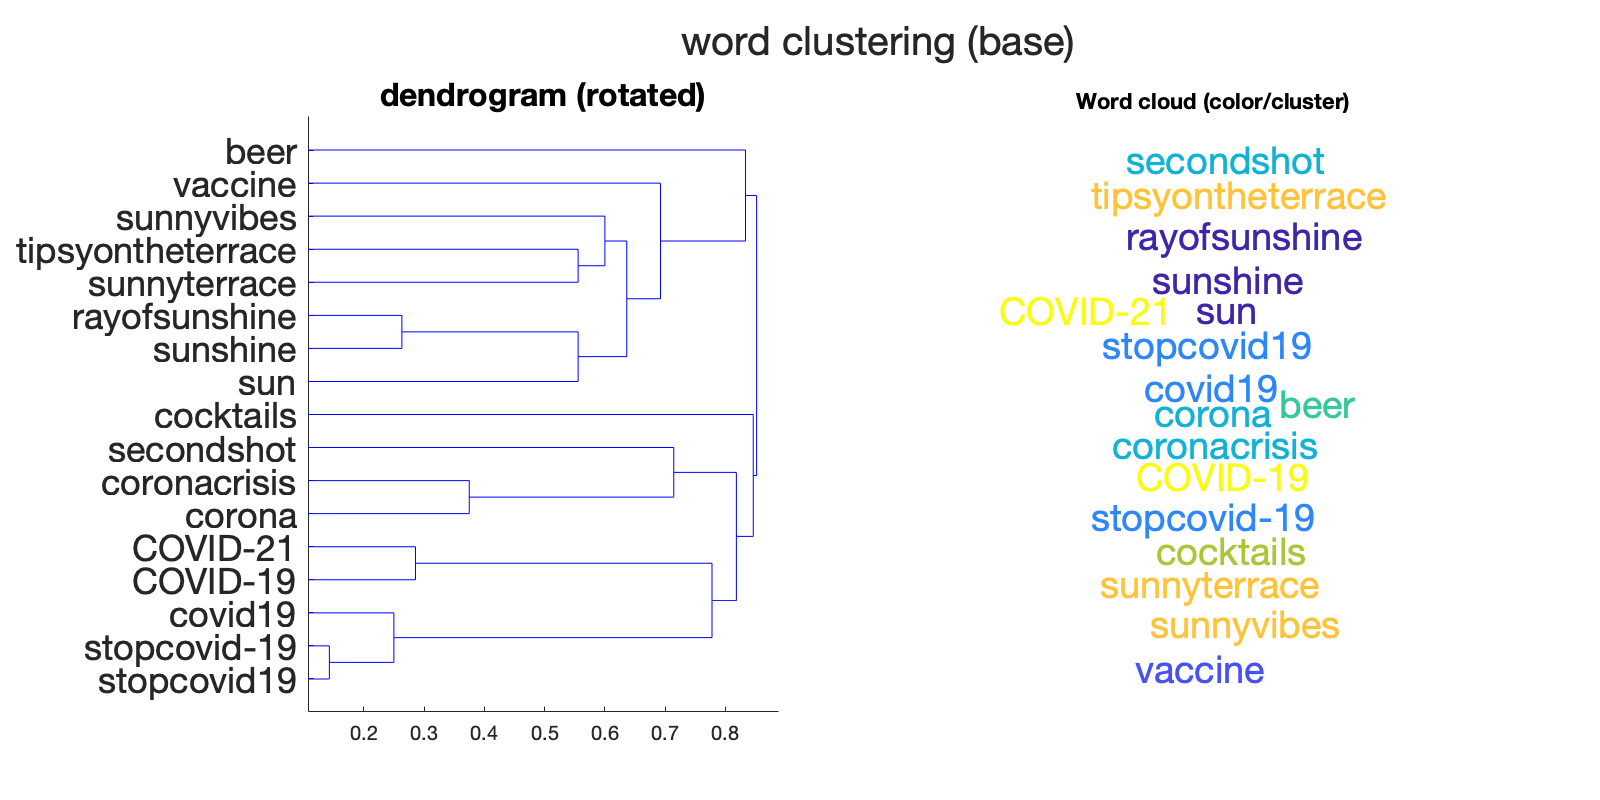

% copy of distance vector
DD = D;
% find index of distance between beer and vaccine
d_bv = dicedistance(tags(10), tags(15));
M = length(tags);
i = 15; j = 10;
idxstart = (j-1)*M - j*(j-1)/2; 
pos = idxstart+i-j;
% set value small
DD(pos) = 1e-2;


% find index of distance between COVID-19 and COVID-21
d_1921 = dicedistance(tags(4), tags(17));
i = 17; j = 4;
idxstart = (j-1)*M - j*(j-1)/2; 
pos = idxstart+i-j;
% set value large
DD(pos) = 1;

% rerun clustering
% get tree
ZZ = linkage(DD);
% get clusters
CC = cluster(ZZ,'Cutoff',0.8);
% illustration
figure("Position",[0 0 800 400])
t = tiledlayout(1,2);
t.Title.String = "word clustering (semantic link)";
t.Title.FontSize = 20;
nexttile
[H,T,outperm] = dendrogram(ZZ,"Orientation","right");
yticklabels(tags(outperm))
ax = gca;
ax.YAxis.FontSize = 18;
title("dendrogram (rotated)","FontSize",16)
nexttile
wordcloud(tags,ones(size(tags)),'Color',getcolors(CC-1))
title("Word cloud (color/cluster)")

What other improvements could be realised here?

## DBSCAN

The final clustering method is DBSCAN, which is a density based clustering method. The algorithm is defined by two parameters:

- MinPts: number of point required to be considered a core point

- eps: radius used for the density. Each point within this radius contributes to the density

Using density and a minimum amount of required points has tha advantage of being resistant to noise.

### Basic usage

below we use BDSCAN on the data with an outlier that proved to be a problem when using kmeans clustering. The Matlab implementation returns the cluster index. A value of -1 indicates a noise point.

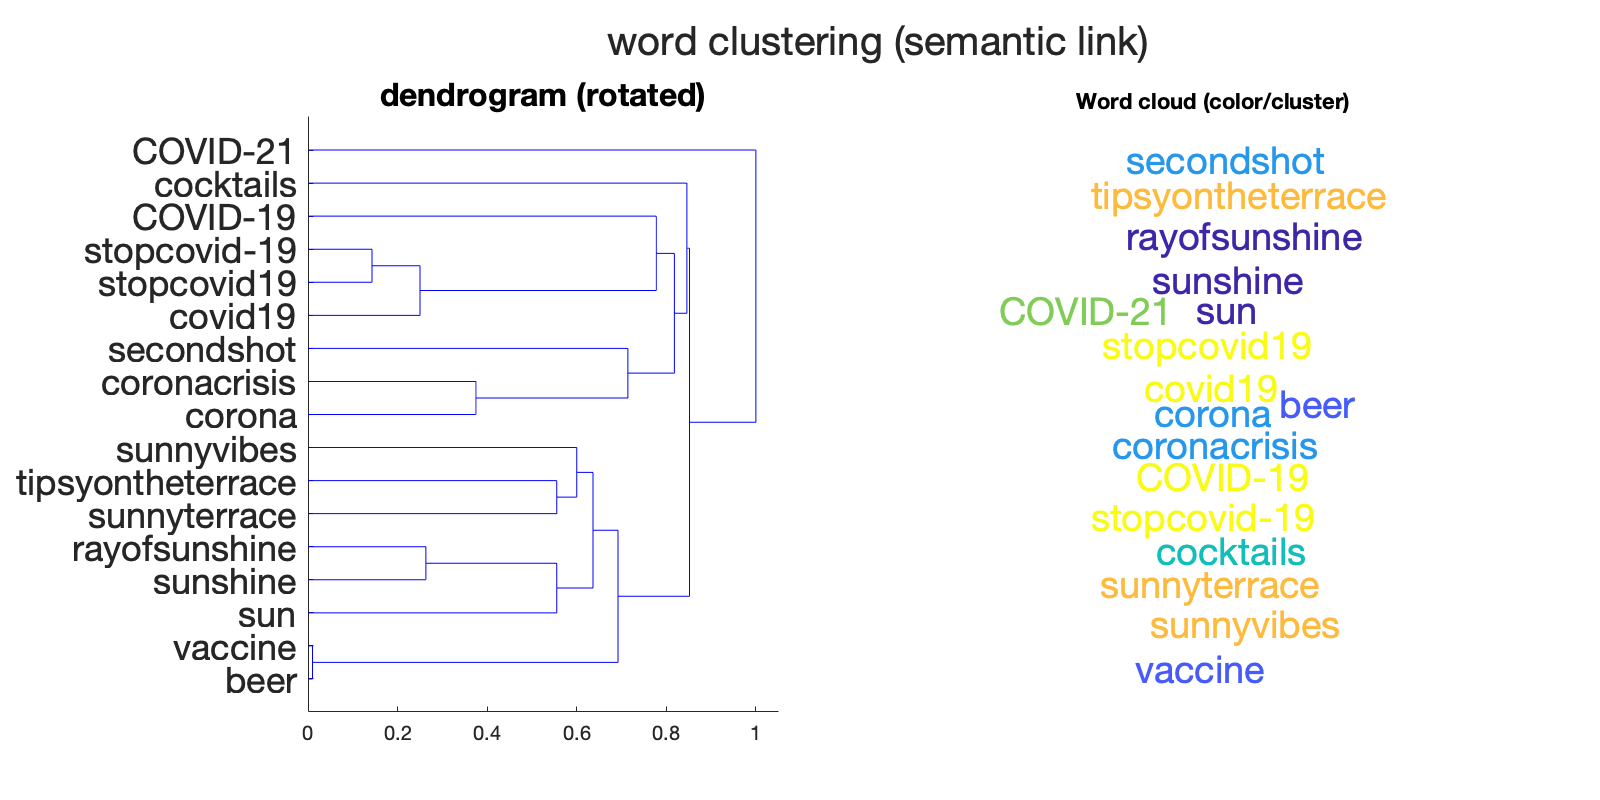

% make some rectangles (same size, different positions)
clear;
rng(1)
[coord, c] = kmeansdata([-2 -2 2 2], [-1 1 -1 1], [1 1 1 1], [1 1 1 1],100);
coord = [coord;[40 1]];
c = [c; repmat([0 0 0],1,1)];

% use dbscan
epsilon = 0.2;
MinPts = 4;
idx = dbscan(coord,0.3, 6);
noisepts = idx == -1;
clusters = idx ~= -1;

% illustration
figure("Position",[0 0 1200 300])
subplot(1,2,1)
scatter(coord(:,1), coord(:,2),20,c,'o','filled'); hold on
title("initial data with centroids",'FontSize',20)
subplot(1,2,2)
scatter(coord(noisepts,1),coord(noisepts,2),20,'black',"displayname","noise points"); hold on
scatter(coord(clusters,1),coord(clusters,2),20, getcolors(idx(clusters) - 1),"filled","displayname","clusters")
title(sprintf("clustered data and ouliers (MinPts = %i, \\epsilon = %1.2f)",MinPts,epsilon),'FontSize',20)
legend("location","southeast",'FontSize',12);

As you can see, this works relatively well. 

### Adequate algorithm settings

Find optimal setting is a bit less straight forward. As a guideline:

- *minPts* should be at least one greater than the number of dimensions of the dataset. Generally, it is twice the dimensions. Domain specifiv knowledge can provide additional info.

- *eps*: determine a value from the k-distance graph. The point of maximum curvature (elbow) in this graph tells us about the value of *eps*. If the value of *eps* chosen is too small then a higher number of clusters will be created,  and more data points will be taken as noise. Whereas, if chosen too big  then various small clusters will merge into a big cluster, and we will  lose details.

Below, different k-distance graphs are generated. The optimal value for *eps* is estimated using:

- a numerical approximation for the curvature (2nd derivative).

- a change in signal using linear approximation

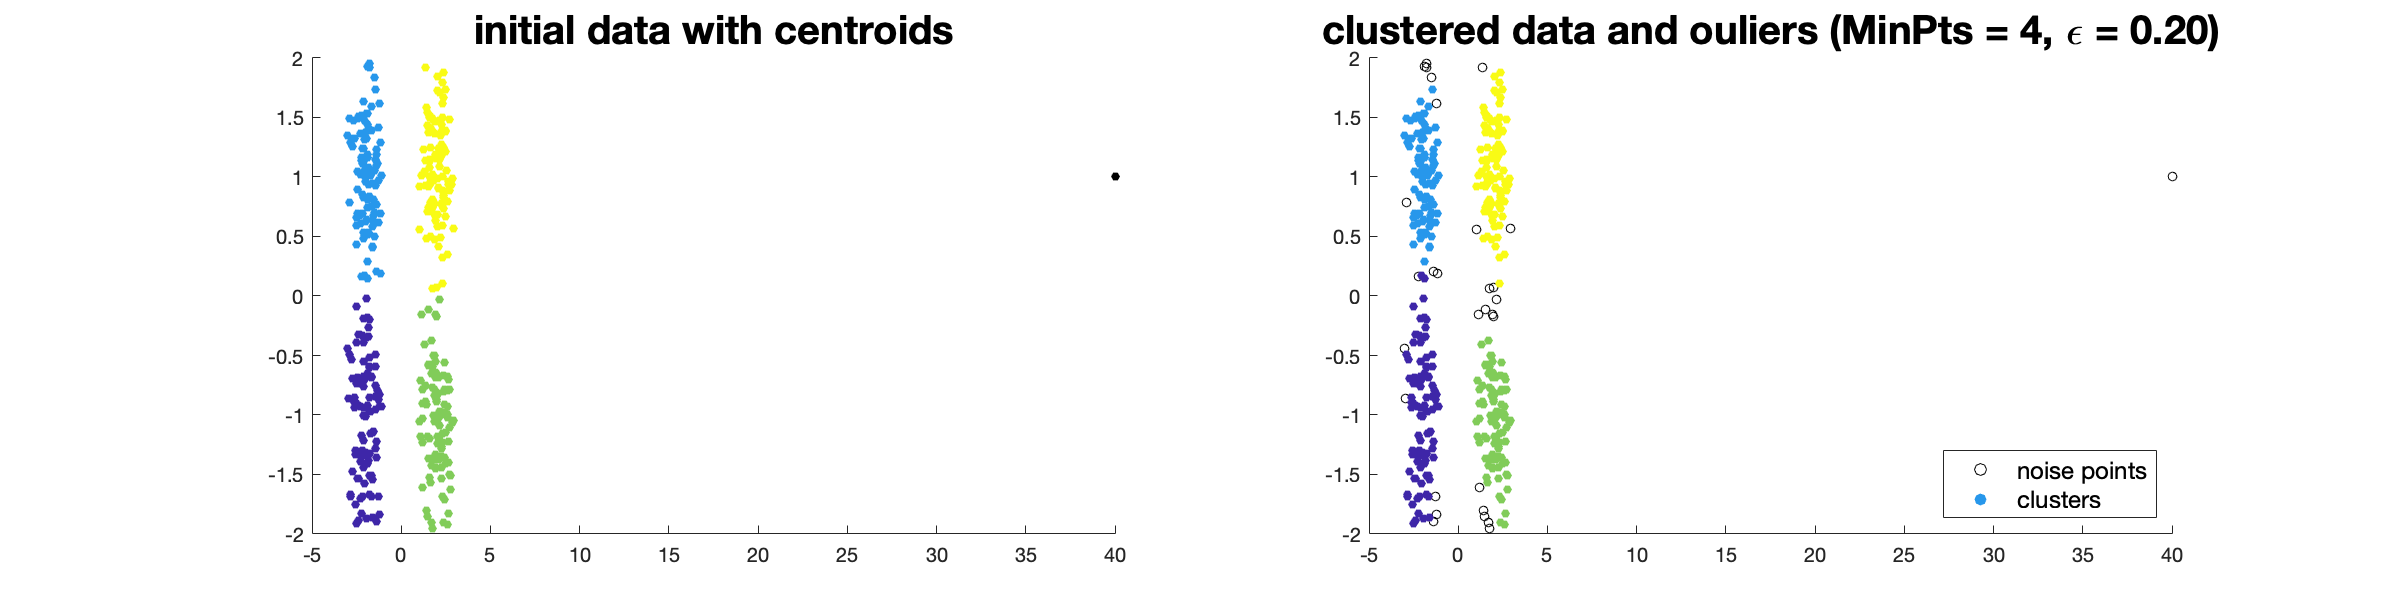

figure("position",[0 0 1200,600]);
%mdl = ExhaustiveSearcher(coord);
    
t = tiledlayout(2,4);
for k = 1:8
    nexttile
    % find k nearest neighbor distance for each point
    [~, D] = knnsearch(coord, coord,'k',k+1); % +1 because the point itself is included in the training data
    y = sort(D(:,end)); 
    % removal of x outlier(s)
    n_remov = 4; 
    % using change in signal
    cidx = findchangepts(y(1:end-n_remov), "Statistic","linear");
    % max curvatur
    curv = y(1:end-2-n_remov) - 2*y(2:end-1-n_remov) + y(3:end-n_remov);
    [mc, mi] = max(curv);
    % illlustration 
    plot(y);
    hold on
    plot(cidx, y(cidx),'xr');
    plot(mi+1, y(mi+1),'sr');

    title(sprintf('k = %i',k),'fontsize',16)
    ylim([0 1])
    ylabel(sprintf("%ith nearest neighbor distance",k),'fontsize',13)
    legend(["k-nearest neighbor plot" sprintf("change signal (eps = %1.2f)", y(cidx)) sprintf("max curvature (eps = %1.2f)", y(mi+1))])
end

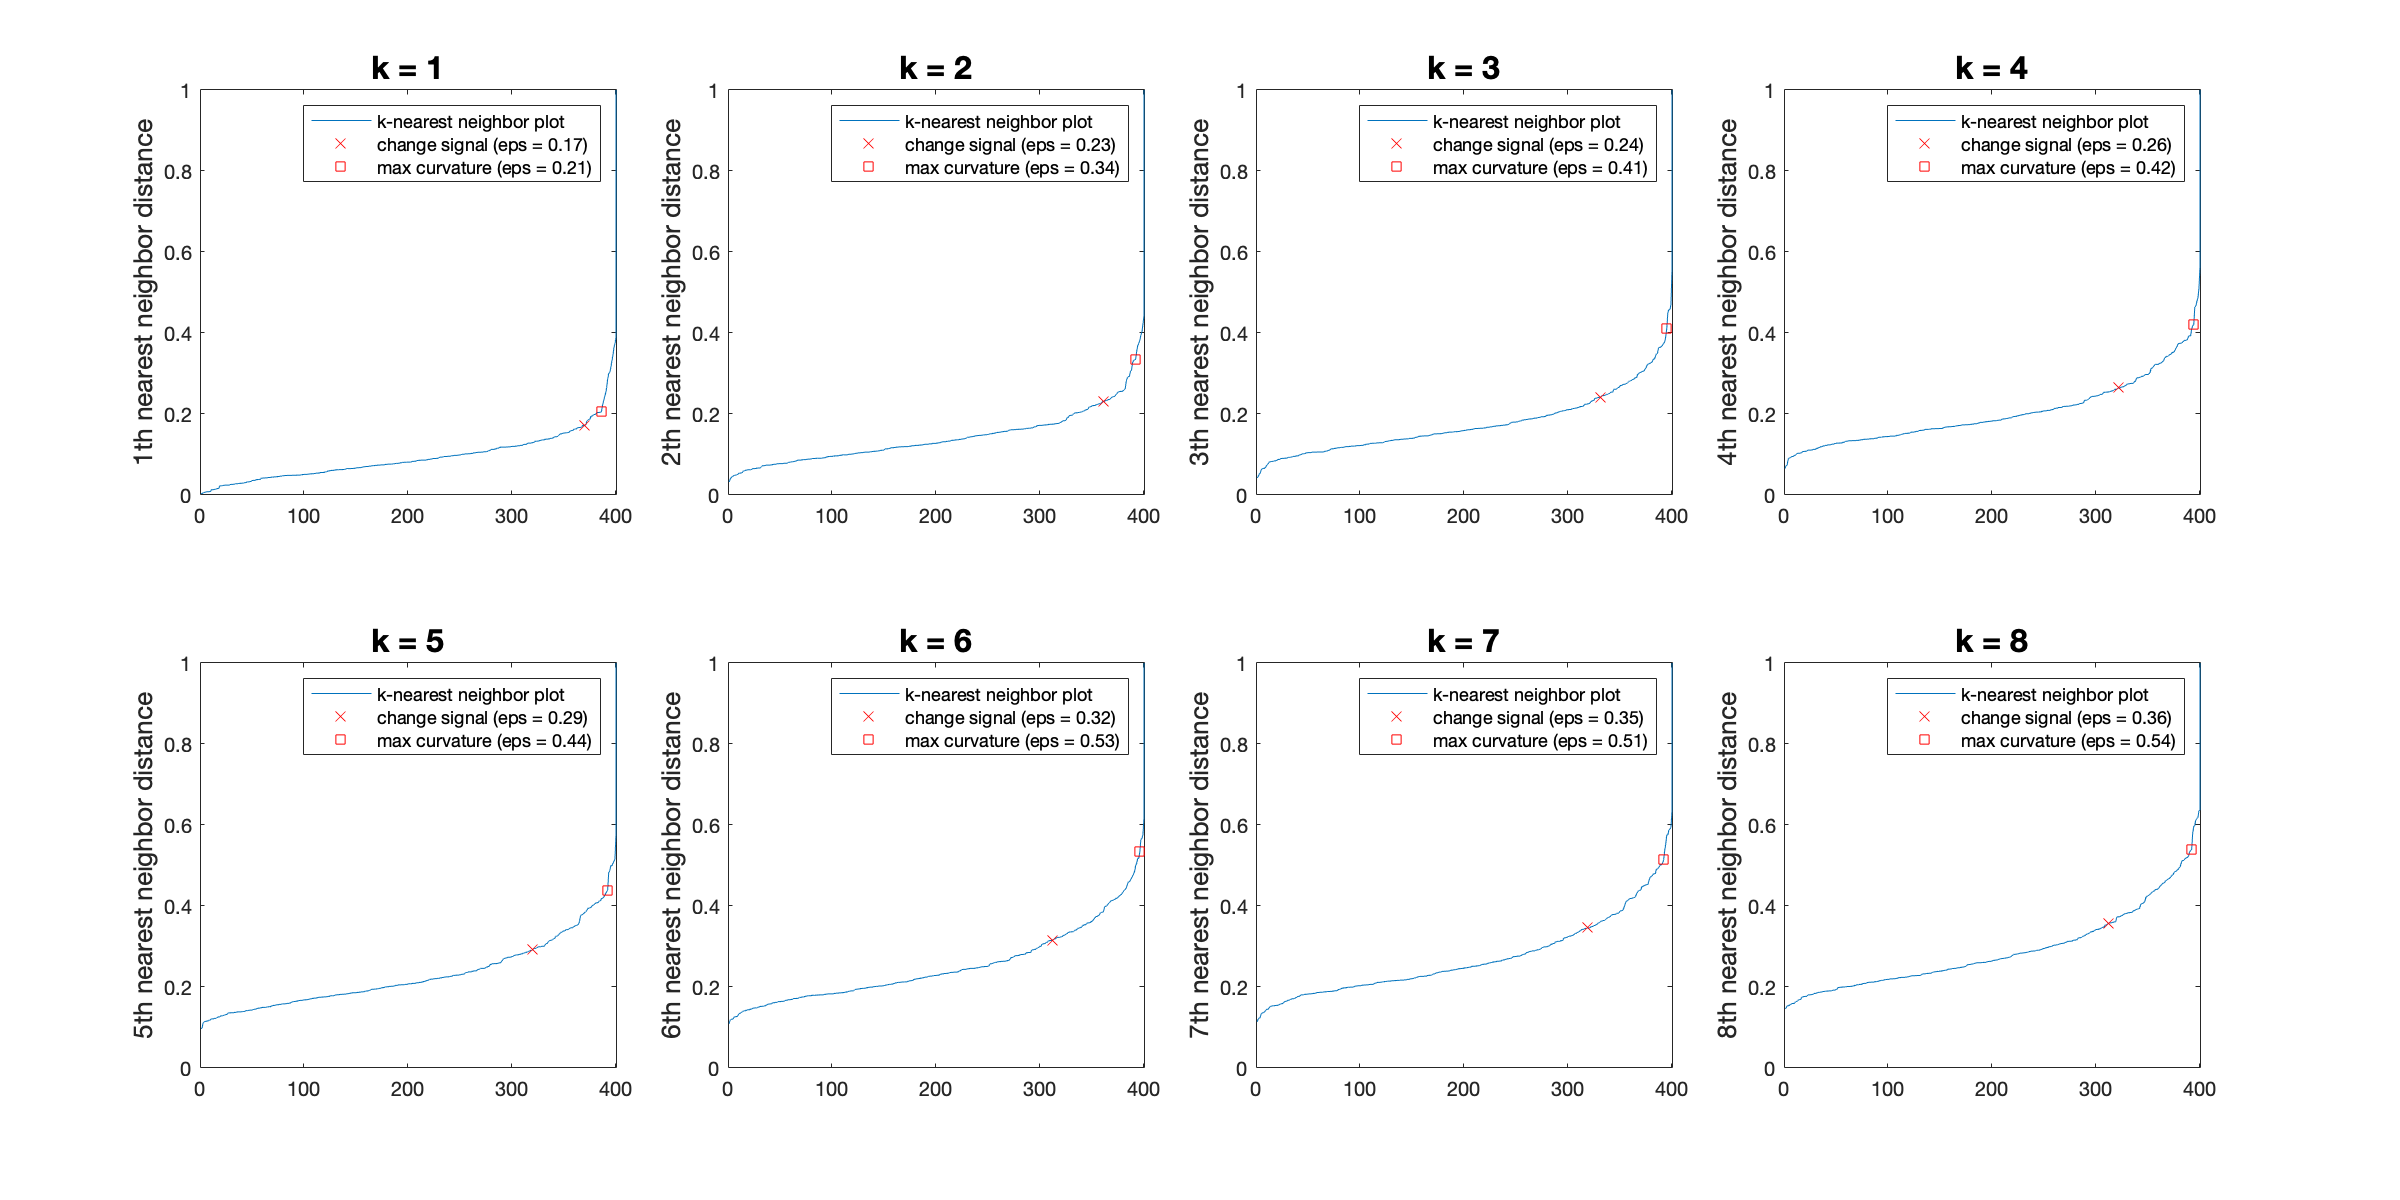

function res = ddist(X,named)
    % dice similarity function similar to pdist
    arguments
        X
        named.k = 2
    end
    M = length(X);
    res = zeros(1,M*(M-1)/2);
    for j = 1:M-1
        idxstart = (j-1)*M - j*(j-1)/2; 
        for i = j+1:M
            res(idxstart+i-j) = dicedistance(X(i), X(j),'k',named.k);
        end
    end
end

function S = dicedistance(a,b,named)
    % dicedistance determine the dice distance between two words using
    % k-shingles (2 by default)
    arguments
        a
        b
        named.k = 2
    end
    % transform the words to shingles
    A = shingle(a,named.k);

    B = shingle(b,named.k);
    % compute 1-S (for distance)
    S = 1 - 2*length(intersect(A,B)) / (length(A) + length(B));
end

function r = shingle(w, k)
    assert(k <= strlength(w),"shingle length can't be superior to the word length")
    r = strings(strlength(w)-(k-1),1);
    for i = 1:length(r)
        r(i) = extractBetween(w,i,i+k-1);
    end
end
function [bag, f, c] = preprocesstext(bag, folder,f,c)
    % preprocesstext prepare text for TFIDF representation
    %
    % [bag, f, c] = preprocesstext(bag, folder) Load all txt files in a
    % folder and add them to the bagofwordsobject. 
    %
    % returns:
    % - bag : bagofwords representation
    % - f : list of file names used for the bag
    % - c : list of labels (extracted from filename)
    arguments
        bag
        folder
        f = []
        c = []
    end
    % get all files in folder
    files = dir(sprintf("%s*.txt",folder));
    rr = cellfun(@(x) sprintf("%s%s",folder,x),{files.name});
    f = [f;rr'];
    % get labels     
    label = split(folder,'/');
    label = label(end-1);
    c = [c;repmat(sprintf("%s",label),length(files),1)];
    % do the preprocessing
    for fname = rr
        % read single file
        doc = extractFileText(fname);
        % transform the single file into a tokenized document
        doc = tokenizedDocument(doc,"Language","en");
        % cleaning up the tokenized document:
        % - lowercase everything
        doc = lower(doc);
        % - punctuation removal
        doc = erasePunctuation(doc);
        % - stop word removal
        doc = removeStopWords(doc);
        % add doc to bag
        bag = addDocument(bag, doc);
    end
end

function res = rectangle(x, y, width, height, n)
    % rectangle returns rectangle coordinates from truncated normal
    % distrubution
    tx = truncate(makedist("Normal", "mu",x,"sigma",width/2), x-width, x+width);
    ty = truncate(makedist("Normal","mu",y,"sigma",height/2), y-height, y+height);
    x = random(tx,n,1);
    y = random(ty,n,1);
    res = [x y];
end

function [coord, c] = kmeansdata(X, Y, W, H, n)
    % kmeansdata - generate rectangular clusters
    % X & Y are vectors with the clusters' centers
    % W & H are vectors with the clusters' width and height
    % n is the number of points per cluster
    %
    % coord contains the coordinates of the points
    % c contains the real label of the cluster
    assert( (length(X)==length(Y)) && (length(W)==length(H)) && (length(Y)==length(W)), "not same input length")
    coord = zeros(length(X)*n,2);
    mycolors = parula(length(X));
    c = zeros(length(X)*n,3);
    for i = 1:length(X)
        coord((i-1)*n+1:i*n, :) = rectangle(X(i),Y(i),W(i),H(i),n);
        c((i-1)*n+1:i*n, :) = repmat(mycolors(i,:),n,1);
    end
end

function c = getcolors(Y)
    mycolors = parula(length(unique(Y)));
    c = zeros(length(Y),3);
    for i = 1:length(Y)
        c(i,:) = mycolors(Y(i)+1,:);
    end
end

function [I] = clusterinertia(X, idx, C)
   % CLUSTERINERTIA compute cluster inertia
   %
   % clusterinertia(X, idx, C) computes cluster inertia for points X with
   % membership idx and centroids C.
   I = zeros(1,1);
   for c = 1:size(C,1)
        % filter datapoints
        I = I + sum((X(idx==c,:) - C(c,:)) .^2, 'all');
   end
end

function [S] = silhouettecoef(X, idx, C)
   % SILHOUETTECOEF compute cluster silhouette
   %
   % silhouette(X, idx, C) computes silhouette coefficient for points X with
   % membership idx and centroids C.
   S = zeros(size(X,1),1);
   for i = 1:size(X,1)
       % get mean distance for own cluster
       a = sum(sum((X(idx == idx(i),:) - X(i,:)) .^ 2, 2)) / sum(idx == idx(i));
       % get closest non own cluster
       [~,minclust] = mink(sum((C - X(i,:)).^2, 2), 2);
       minclust = minclust(2);
       b = mean(sum((X(idx == minclust,:) - X(i,:)) .^ 2, 2));
       % S_i
       S(i) = (b-a)/max(a,b);
   end
   S = mean(S);
end

function [D] = daviesbouldin(X, idx, C)
   % DAVIESBOULDIN compute davies-bouldin index
   %
   % daviesbouldin(X, idx, C) computes davies-bouldin index for points X with
   % membership idx and centroids C.
   d = zeros(size(C,1), 1);
   dij = zeros(size(C,1), size(C,1));
   D = zeros(size(C,1), 1);
   % compute d
   for c = 1:size(C,1)
      d(c) = mean(sum((X(idx == c,:) - C(c,:)) .^ 2, 2));
      for j = 1:size(C,1)
          dij(c,j) = sum((C(c,:) - C(j,:)).^2);
          if j ~= c
              val = (d(c) + d(j))/dij(c,j);
              if val > D(c)
                  D(c) = val;
              end
          end
      end
   end
   
   D = mean(D);

end